## Main Simulation Script

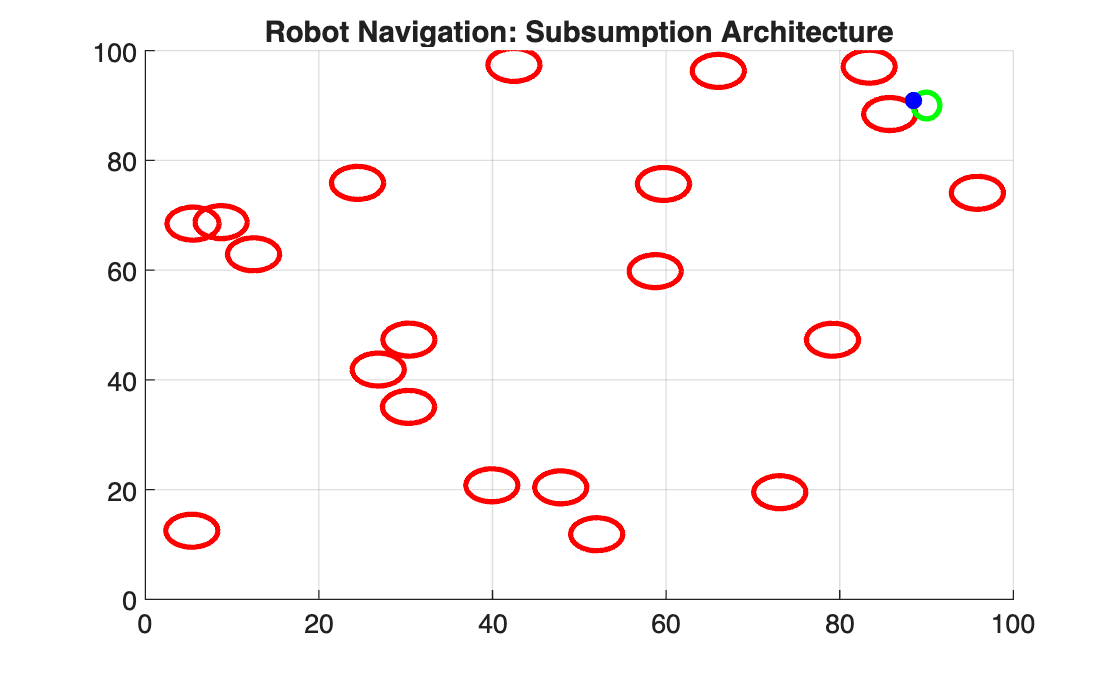

Goal reached in 254 steps!


% Main script for robot navigation using Subsumption Architecture
clear; clc; close all;

%% 1. Initialize Environment
env_size = 100;
num_obstacles = 20;
max_steps = 300;
dt = 0.5; % Time step

% Random obstacles: [x, y, radius]
obstacles = [rand(num_obstacles, 2) * env_size, ones(num_obstacles, 1) * 3];
goal = [90, 90];
robot_state = [10, 10, pi/4]; % [x, y, theta]

% Velocity Limits
v_max = 5.0;
w_max = pi/4;

%% 2. Setup Visualization
figure('Color', 'w');
hold on; grid on;
axis([0 env_size 0 env_size]);
title('Robot Navigation: Subsumption Architecture');

% Plot obstacles
viscircles(obstacles(:,1:2), obstacles(:,3), 'EdgeColor', 'r');
% Plot goal
plot(goal(1), goal(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
% Robot handle
h_robot = plot(robot_state(1), robot_state(2), 'bo', 'MarkerFaceColor', 'b');

%% 3. Simulation Loop
for step = 1:max_steps
    % --- SUBSUMPTION LOGIC (Priority Hierarchy) ---
    
    % Layer 1: Obstacle Avoidance (Highest Priority)
    [v_obs, w_obs, active_obs] = behavior_obstacle_avoidance(robot_state, obstacles, v_max, w_max);
    
    % Layer 2: Goal Seeking (Medium Priority)
    [v_goal, w_goal] = behavior_goal_seeking(robot_state, goal, v_max, w_max);
    
    % Layer 3: Random Wander (Lowest Priority)
    [v_wander, w_wander] = behavior_wander(v_max, w_max);
    
    % Decision Mechanism (Subsumption)
    %This is where the hierarchy is enforced.
    %The active_obs flag is the "panic button." If the obstacle avoidance layer detects a collision risk,
    %  it "subsumes" (overwrites) the goal-seeking behavior. 
    % The robot will stop trying to reach the goal and focus entirely on not crashing.
    if active_obs
        v = v_obs; w = w_obs;
    elseif norm(robot_state(1:2) - goal) > 2
        v = v_goal; w = w_goal;
    else
        v = v_wander; w = w_wander;
    end
    
    % --- KINEMATICS UPDATE ---
    %It calls unicycle_kinematics to calculate where the robot should be 0.5 seconds 
    % (dt) into the future based on the chosen speed (v) and turn rate (w).
    robot_state = unicycle_kinematics(robot_state, v, w, dt);
    
    % --- VISUALIZATION UPDATE ---

    set(h_robot, 'XData', robot_state(1), 'YData', robot_state(2)); %This moves the blue dot to the new x,y position.
    drawnow; %This tells MATLAB, "Stop calculating for a millisecond and actually refresh the screen so we see the movement.
    
    % --- CHECK TERMINATION ---
    %The norm function calculates the straight-line distance between the robot and the goal. 
    % If that distance is less than 2 units, the robot considers itself "arrived," 
    % prints a success message to the command window, and the break command stops the loop early.
    if norm(robot_state(1:2) - goal) < 2
        fprintf('Goal reached in %d steps!\n', step);
        break;
    end
end

## Supporting Functions

### 1.Behavior: Obstacle Avoidance

function [v, w, active] = behavior_obstacle_avoidance(state, obstacles, v_max, w_max)
    detection_radius = 5; %This is the "bubble" around the robot. 
    % If a red circle enters this 8-unit zone, the robot panics.
    v = 0; w = 0; active = false;
    
    for i = 1:size(obstacles, 1)
        dist = norm(state(1:2) - obstacles(i, 1:2)) - obstacles(i, 3); %This calculates the distance 
        % from the robot's center to the edge of the obstacle.
        if dist < detection_radius
            active = true;
            % Calculate angle to obstacle
            angle_to_obs = atan2(obstacles(i,2) - state(2), obstacles(i,1) - state(1));
            % Turn away from the obstacle
            angle_diff = angdiff(state(3), angle_to_obs);
            w = -sign(angle_diff) * w_max; %This is the "steering" logic. 
            % If the obstacle is to the right, the robot turns left (and vice-versa)
            v = v_max * 0.5; % Slow down while turning
            return; % Focus on the nearest threat
        end
    end
end


### 2.Behavior: Goal Seeking

function [v, w] = behavior_goal_seeking(state, goal, v_max, w_max)
    angle_to_goal = atan2(goal(2) - state(2), goal(1) - state(1)); %It looks at the (X,Y) 
    % of the green dot and calculates the angle needed to face it.
    angle_diff = angdiff(state(3), angle_to_goal);
    
    w = max(min(angle_diff, w_max), -w_max);%calculates the turn needed to face the goal, 
    % but ensures the robot doesn't try to turn faster than its physical limit
    v = v_max; %As long as it's heading toward the goal, it drives at full speed.
end

### 3. Behavior: Wander

%If there is no goal and no obstacles, the robot just explores.
function [v, w] = behavior_wander(v_max, w_max)
    v = v_max * 0.8; %It moves slightly slower than top speed.
    w = (rand - 0.5) * 2 * w_max; %This generates a random number between −1 and 1. 
    % This makes the robot wiggle left and right randomly as it moves forward, 
    % preventing it from getting stuck in a straight line forever.
end

### **4. Kinematics**

%This function translates the robot's "thoughts" into actual movement. It uses the Unicycle Model equations:
function next_state = unicycle_kinematics(state, v, w, dt)
    theta = state(3);
    new_x = state(1) + v * cos(theta) * dt; %Calculates the change in horizontal position.
    new_y = state(2) + v * sin(theta) * dt; %Calculates the change in vertical position.
    new_theta = state(3) + w * dt; %Updates which direction the robot is facing.
    next_state = [new_x, new_y, new_theta];
end